%Ex3

clear variables;
n = -5:5;
delta = @(n) (n==0);
alfa = 0.05;
u = @(n) (n>=0);
x_n = @(n) (delta(n) - alfa*delta(n-1));
h1_n = @(n) alfa*u(n);
sx = 0; ex = 1; dtx = sx : ex;
sh = 0; eh = 5; dth = sh : eh;
h2_n = @(n) sin(8*n);
S1_n = @(n) conv(x_n(dtx), h1_n(dth))

S1_n = function_handle with value:
    @(n)conv(x_n(dtx),h1_n(dth))


output = conv(S1_n(dth), h2_n(dth))

output =          0    0.0495    0.0326   -0.0120    0.0179    0.0538    0.0519    0.0024    0.0193    0.0638    0.0340   -0.0019


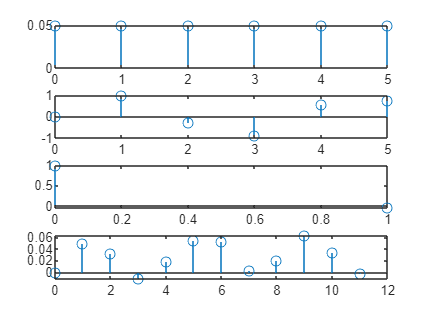

dto = 0:11;
figure,
subplot(4,1,1);stem(dth, h1_n(dth));
subplot(4,1,2);stem(dth, h2_n(dth));
subplot(4,1,3);stem(dtx, x_n(dtx));
subplot(4,1,4);stem(dto, output);